# Counting photons at the sensor surface

We learn a great deal about image quality and noise limits by counting the mean number of photons at each pixel. ISETCam uses physical units throughout, making it straightforward to calculate the number of incident photons at a pixel.  We also learn something by accounting for the fact that the number of photons is Poisson distributed.

This script calculates the mean number of photons we might expect at a pixel in an image sensor.  In ISETCam the image just prior to transduction by the sensor is called the optical image. The initial calculation is for the mean number of photons in a $1\;\mu {\textrm{m}}^2$ patch during 1 sec exposure duration.  Then we calculate the signal-to-noise (mean divided by standard deviation).  We do the calculation at an ambient level of a dimly light classroom.

## Initialize ISETCam 

ieInit

## Create a uniform scene

The luminance level is set to A moderately lit living room at night: Imagine a room with a few lamps on, but not overly bright. If you're  reading a book with a standard table lamp, the page might be closer to 50-100 nits, but the overall average luminance of the entire room (walls, furniture, shadows) could easily be around 10 nits ($\textrm{cd}/m^2$).

For this calculation, I chose 30 nits.  You can scale, as you like.

scene = sceneCreate('uniform equal photon',[512 512]);
scene = sceneSet(scene,'mean luminance',30);

## Create spectral irradiance at the sensor for optics with a range of f#

oi = oiCreate('diffraction limited'); 

% Region in the OI we will measure
roiRect = [291 202 16 23];

% Loop for different f numbers.  Each F/# has an aperture diameter
% that we use, later.
fnumbers = 2:16;

% Store the total number of photons here.
totalQ = zeros(1,length(fnumbers));

% Store the aperture diameter in mm for each fnumber here
apertureD = zeros(size(totalQ));


In ISETCam, the optical image (oi) lets the user specify the focal length and F/#.  The aperture size is the focal length divided by the aperture.  So, if we set the F/#, the focal length remains the same but the aperture changes.  So we loop through the calculation, adjusting the F/# which effectively changes the aperture.

for ff = 1:length(fnumbers)
    oi = oiSet(oi,'optics fnumber',fnumbers(ff));
    oi = oiCompute(oi,scene);
    apertureD(ff) = oiGet(oi,'optics aperture diameter','mm');

    % This is the mean number of photons in the samples within the
    % region of interest. The units of photons are photons/sec/m^2/nm
    spectralIrradiance = oiGet(oi,'roi mean photons',roiRect);
    
    % We sum across all wavelengths to obtain the total
    totalQ(ff) = sum(spectralIrradiance);
end

## Plot the number of photons as a function of aperture diameter (F/#)

Cameras typically have a couple of millisecond exposure duration and a pixel area of about $1\;\mu {\textrm{m}}^2$ .  So, let's calculate for those  parameters. These values are of some interest to vision scientists, too. In the central fovea, the aperture of such a receptor is about $1\;\mu {\textrm{m}}^2$ and the integration time of the cone photoreceptors is about 30 ms.  The human F/# is about 5.

Remember, we have already summed the photons of all wavelengths. For a color image sensor, we would measure the different wavebands separately.  

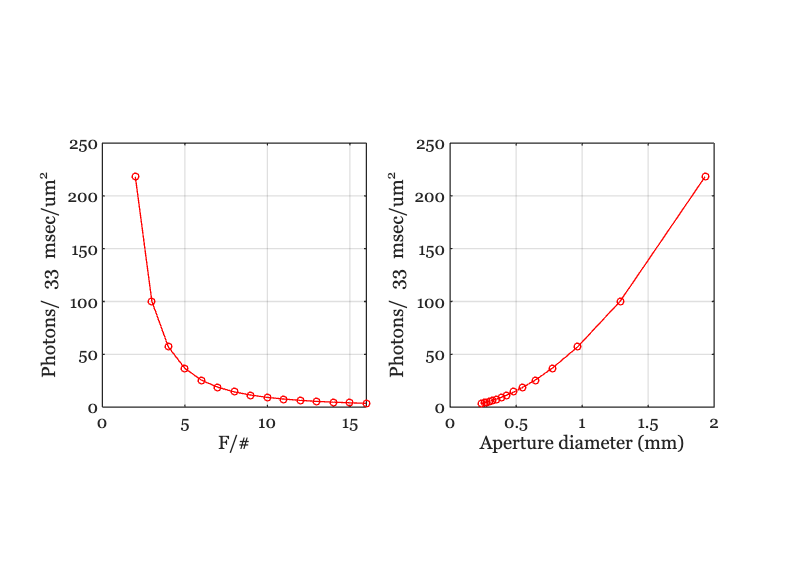

expTime   = 1/30;         % 1 / frames per second
pixelArea = (1e-6)^2;     % 1 square micron
sFactor   = pixelArea*expTime;  % Total scale factor

ieFigure;
subplot(1,2,1);
plot(fnumbers,totalQ*sFactor,'-o'); axis square
grid on; xlabel('F/#'); 
ylabel(sprintf('Photons/ %d msec/{um}^2',round(expTime*1e3)));

subplot(1,2,2);
plot(apertureD,totalQ*sFactor,'-o'); axis square
grid on; xlabel('Aperture diameter (mm)'); 
ylabel(sprintf('Photons/ %d msec/{um}^2',round(expTime*1e3)));

## Signal-to-noise as a function of F/#

The signal-to-noise ratio (SNR) measures the size of the signal in terms of standard deviations.  For example, if the mean is 100 and the standard deviation is 10, the SNR is 10.

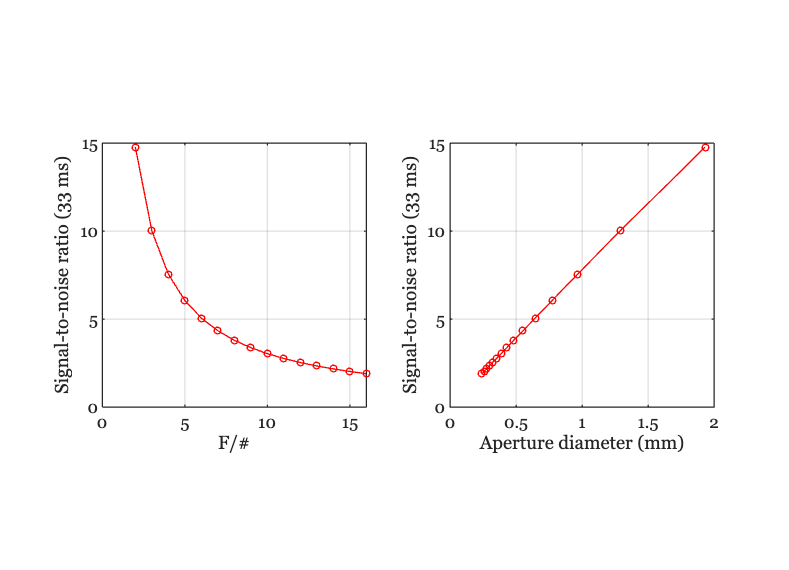

SNR = totalQ*sFactor ./ sqrt(totalQ*sFactor);

ieFigure;
subplot(1,2,1);
plot(fnumbers,SNR,'-o'); axis square
grid on; xlabel('F/#'); 
ylabel(sprintf('Signal-to-noise ratio (%d ms)',round(expTime*1e3)));

subplot(1,2,2)
plot(apertureD,SNR,'-o'); axis square
grid on; xlabel('Aperture diameter (mm)'); 
ylabel(sprintf('Signal-to-noise ratio (%d ms)',round(expTime*1e3)));